Put M, m, hm, hM into matrix. Find 4-note chords, printing intervals, key, mode, scale, and notes.

M=[2 2 1 2 2 2 1];  %Major
m=[2 1 2 2 2 2 1];   %melodic minor
hm=[2 1 2 2 1 3 1];  %harmonic minor
hM=[2 2 1 2 1 3 1];  %harmonic Major

scaleMatrix=[M; m; hm; hM];
scaleMatrix2=cat(2,scaleMatrix,scaleMatrix);

n=0;
chordsModesKeysScalesRoots=[];
for K=0:11                                  % goes through keys
    for s=1:4                               % goes through scales
        for i=1:7                           % goes through modes
            for j=(i+1):i+6
               for k=(j+1):i+6
                  for l=(k+1):i+6
                       n=n+1;
                       int1=sum(scaleMatrix2(s,i:j-1));         %------------
                       int2=sum(scaleMatrix2(s,j:k-1));         % four intervals
                       int3=sum(scaleMatrix2(s,k:l-1));         %
                       int4=sum(scaleMatrix2(s,l:i+6));         %------------
                       note1=mod(K+sum(scaleMatrix2(s,1:i))-scaleMatrix2(s,i),12);  %------------
                       note2=mod(note1+int1,12);                                    % four notes
                       note3=mod(note2+int2,12);                                    %
                       note4=mod(note3+int3,12);                                    %------------
                       chordsModesKeysScalesRoots(end+1,:)=[int1, 
                        int2, 
                        int3, 
                        int4,
                        i,                       % mode  
                        K,                       % key   
                        s,                       % scale 
                        note1, 
                        note2, 
                        note3, 
                        note4];
                    end
               end
           end
        end
    end    
end

Group together chord families.

sameChordNotes=[];
m=0;
for i=1:size(chordsModesKeysScalesRoots,1) % i runs down rows of chordsModesKeysScalesRoots
    if ismember(i,sameChordNotes)==0 %  checks if row number has already been assigned to a family in sameChordNotes
        n=0; % resets sameChordNotes column to 0
        m=m+1; % increments sameChordNotes row for next entries
        for j=i:size(chordsModesKeysScalesRoots,1) % checks all chords (there can't be any BEFORE i in same family, because then i would have been entered in sameChordNotes)
            for k=0:3
                if isequal(chordsModesKeysScalesRoots(j,[8:11]),circshift(chordsModesKeysScalesRoots(i,[8:11]),k))==1 % checks if the notes are exactly the same
                    n=n+1;
                    sameChordNotes(m,n)=j;
                end
            end        
        end   
    end
end

Create adjacency matrix for graph, then build graph.

adjMat=zeros(393);
for i=1:size(sameChordNotes, 1) % goes through 393 families
    noteGroup=chordsModesKeysScalesRoots(sameChordNotes(i,1),8:11); % gets original chord to modify
    for j=1:4 % goes through chord note by note
        if mod(noteGroup(j)+1,12)~=noteGroup(1+mod((j-1)+1,4)) % makes sure you don't create illegal comparison chord
            cfNoteGroup=noteGroup;
            cfNoteGroup(j)=mod(noteGroup(j)+1,12); % creates modified chord to compare
            for k=1:size(sameChordNotes, 1) % goes through families 
                if k~=i && adjMat(i,k)~=1
                    inSameChordNotes=chordsModesKeysScalesRoots(sameChordNotes(k,1),8:11); % member of family to compare
                    for l=0:3
                        if isequal(inSameChordNotes, circshift(cfNoteGroup,l))==1 
                            adjMat(i,k)=1; % enters 1 in adjacency matrix
                            adjMat(k,i)=1; % (adjacency matrix is symmetric)
                        end
                    end
                end
            end
        end
    end
end

G=graph(adjMat);

Do random walk on graph to generate first page.

x=randi(393);
seq=[x];
for i=1:7 %for 8-chord sequence (x is first)
    N=neighbors(G,x);
    next=randi(size(N,1));
    x=N(next);
    seq(end+1)=x;
end
%seq' % un-comment this line to display the nodes traversed



Option to continue random walk from last node of previous run, if you want to create a second page of the exercise.  

y=seq(8); % start from last node on previous page
seq2=[y];
for i=1:8 % for 8-chord sequence (y is first -- we delete the y entry later)
    N=neighbors(G,y);
    next=randi(size(N,1));
    y=N(next);
    seq2(end+1)=y;
end
seq2=seq2(2:9);

Plot graph and highlight traversed nodes.  

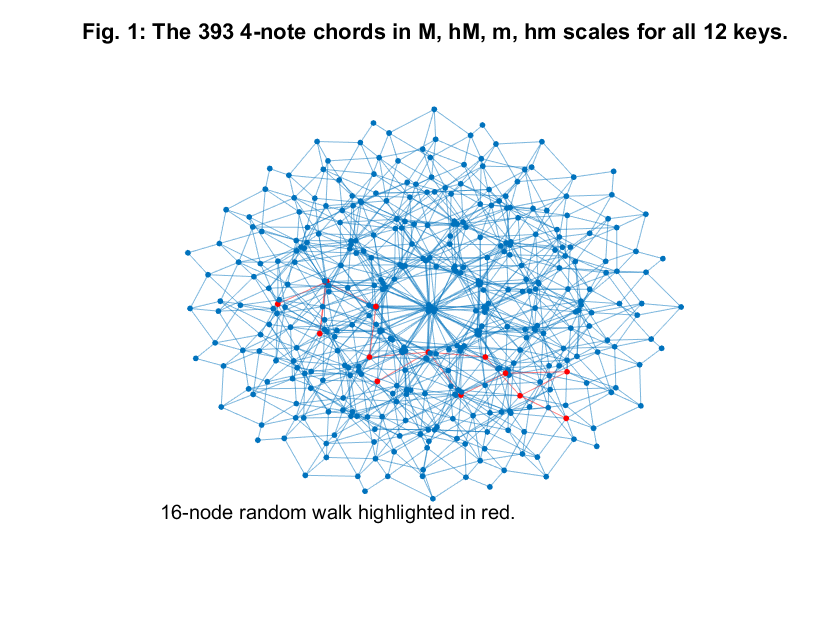

h=plot(G);
box off;
set(gca,'XColor','none','YColor','none');
highlight(h,[seq seq2],'NodeColor','r', 'EdgeColor','r');
title('Fig. 1: The 393 4-note chords in M, hM, m, hm scales for all 12 keys.')
text(-6.4,-6,'16-node random walk highlighted in red.')

First page (using `seq`): Print notes, keys, scales from random walk --- formatted for the LaTeX PSTricks file.  

keyMaster=["C", "\nicefrac{C$^\sharp$}{D$^\flat$}", "D", "\nicefrac{D$^\sharp$}{E$^\flat$}", "E", "F", "\nicefrac{F$^\sharp$}{G$^\flat$}", "G", "\nicefrac{G$^\sharp$}{A$^\flat$}", "A", "\nicefrac{A$^\sharp$}{B$^\flat$}", "B"]; % all flat

scaleMaster=["M","m","hm","hM"];
toInsert=strings(0);
for i=1:length(seq)
    [~,ind]=min(sameChordNotes(seq(i),:)); % finds first zero entry in row of chord family
    if ind==1 % this is what happens if there are no zeros; the first entry is always the minimum
        famMat=chordsModesKeysScalesRoots(sameChordNotes(seq(i),1:size(sameChordNotes,2)),:); % size(sameChordNotes,2) = 32
    else 
        famMat=chordsModesKeysScalesRoots(sameChordNotes(seq(i),1:ind-1),:); % makes matrix with all family info
    end
    [~,startNote]=min(famMat(:,8));
    famNotes=keyMaster(famMat(startNote,8:11)+1);
    possibleKeys=strings(0);
    for j=1:4:size(famMat,1)
        % the same combination appears 4 times in a row; this skips 3 of them
        if j>1 && keyMaster(famMat(j,6)+1)==keyMaster(famMat(j-4,6)+1)
            possibleKeys(end+1)=strcat(" ", keyMaster(famMat(j,6)+1), "$_{", scaleMaster(famMat(j,7)), "}$ ");
        else 
            possibleKeys(end+1)=strcat("\\", keyMaster(famMat(j,6)+1), "$_{", scaleMaster(famMat(j,7)), "}$ ");
        end
    end
    toInsert(end+1)=strcat("\textbf{", join(famNotes), "} \small ", join(possibleKeys));  % prepares strings to print with LaTeX syntax
end

% A future release will make the spacing between scales look more pleasant.

First page (using `toInsert`):  Create PSTricks LaTeX file with chord sequence.

old_filespec = 'picture_file_template.txt';
new_filespec = sprintf('picture_file_%s_pg1.txt', datestr(now,'mm-dd-yyyy HH-MM'));

insert_here=[2692 2696 2700 2704 2708 2712 2716 2720];
% vector with line numbers to insert text --- these line numbers depend
% upon what's in the PSTricks file. 

    fid = fopen( old_filespec );
    cac = textscan( fid, '%s', 'Delimiter','\n', 'CollectOutput',true );
    fclose( fid );
    fid = fopen( new_filespec, 'w' );
    %now: do this in between each element in insert_here
    for jj = 1 : insert_here(1)-1 
            fprintf( fid, '%s\n', cac{1,1}{jj} ); 
    end  
    for kk = 1 : length(insert_here)-1
        fprintf( fid, '%s\n', toInsert(kk) ); 
        for jj = insert_here(kk)+1 : insert_here(kk+1)-1 
            fprintf( fid, '%s\n', cac{1,1}{jj} ); 
        end 
    end 
    fprintf( fid, '%s\n', toInsert(end) ); 
    for jj = insert_here(end)+1 : length(cac{1,1}) 
            fprintf( fid, '%s\n', cac{1,1}{jj} ); 
    end 
    fclose( fid ); 

Second page (using `seq2`): Print notes, keys, scales from random walk --- formatted for the LaTeX PSTricks file.  

keyMaster=["C", "\nicefrac{C$^\sharp$}{D$^\flat$}", "D", "\nicefrac{D$^\sharp$}{E$^\flat$}", "E", "F", "\nicefrac{F$^\sharp$}{G$^\flat$}", "G", "\nicefrac{G$^\sharp$}{A$^\flat$}", "A", "\nicefrac{A$^\sharp$}{B$^\flat$}", "B"]; % all flat

scaleMaster=["M","m","hm","hM"];
toInsert2=strings(0);
for i=1:length(seq2)
    [~,ind]=min(sameChordNotes(seq2(i),:)); % finds first zero entry in row of chord family
    if ind==1 % this is what happens if there are no zeros; the first entry is always the minimum
        famMat=chordsModesKeysScalesRoots(sameChordNotes(seq2(i),1:size(sameChordNotes,2)),:); % size(sameChordNotes,2) = 32
    else 
        famMat=chordsModesKeysScalesRoots(sameChordNotes(seq2(i),1:ind-1),:); % makes matrix with all family info
    end
    [~,startNote]=min(famMat(:,8));
    famNotes=keyMaster(famMat(startNote,8:11)+1);
    possibleKeys=strings(0);
    for j=1:4:size(famMat,1)
        % the same combination appears 4 times in a row; this skips 3 of them
        if j>1 && keyMaster(famMat(j,6)+1)==keyMaster(famMat(j-4,6)+1)
            possibleKeys(end+1)=strcat(" ", keyMaster(famMat(j,6)+1), "$_{", scaleMaster(famMat(j,7)), "}$ ");
        else 
            possibleKeys(end+1)=strcat("\\", keyMaster(famMat(j,6)+1), "$_{", scaleMaster(famMat(j,7)), "}$ ");
        end
    end
    toInsert2(end+1)=strcat("\textbf{", join(famNotes), "} \small ", join(possibleKeys));  % prepares strings to print with LaTeX syntax
end

Second page (using `toInsert2`):  Create PSTricks LaTeX file with chord sequence.

old_filespec = 'picture_file_template.txt';
new_filespec = sprintf('picture_file_%s_pg2.txt', datestr(now,'mm-dd-yyyy HH-MM'));

insert_here=[2692 2696 2700 2704 2708 2712 2716 2720];
% vector with line numbers to insert text --- these line numbers depend
% upon what's in the PSTricks file. 

    fid = fopen( old_filespec );
    cac = textscan( fid, '%s', 'Delimiter','\n', 'CollectOutput',true );
    fclose( fid );
    fid = fopen( new_filespec, 'w' );
    %now: do this in between each element in insert_here
    for jj = 1 : insert_here(1)-1 
            fprintf( fid, '%s\n', cac{1,1}{jj} ); 
    end  
    for kk = 1 : length(insert_here)-1
        fprintf( fid, '%s\n', toInsert2(kk) ); 
        for jj = insert_here(kk)+1 : insert_here(kk+1)-1 
            fprintf( fid, '%s\n', cac{1,1}{jj} ); 
        end 
    end 
    fprintf( fid, '%s\n', toInsert2(end) ); 
    for jj = insert_here(end)+1 : length(cac{1,1}) 
            fprintf( fid, '%s\n', cac{1,1}{jj} ); 
    end 
    fclose( fid ); 